# **Satellite GSD calculation**

**    한컴인스페이스 위성사업단 김홍석 연구원**

## I. Multiscape 200 Payload Specification

**    Optics**

- Focal Length: 580mm +/- 1mm

- Aperture: 95mm

- Full Field of view: 2.22 deg (Across-track)

**    Imaging**

- Resolution: 4096 pixels

- Pixel size: 5.5 micro-m (5.5* 10^-6 m)

- Pixel Depth: 10-bit

**    General**

- GSD: 4.75 m at 500km

- Swath: 19.4 km at 500km

## II. Case 1: Nadir Angle With Sphere Earth

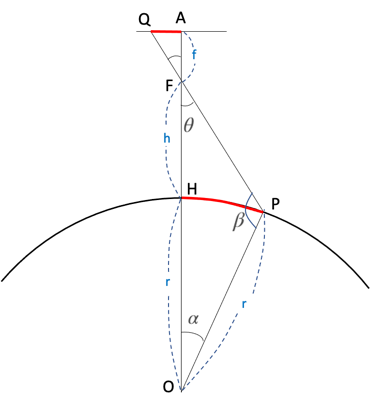    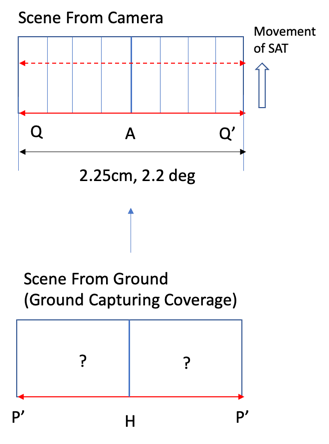


$$\begin{array}{l}
\angle \textrm{AFQ}=\theta ,\;\;\angle \textrm{HOP}=\alpha ,\;\;\angle \textrm{OPF}=\beta \\
\bar{\textrm{AQ}} =x,\bar{\textrm{AF}} =f,\;\;\bar{\textrm{HP}} =y=r\alpha ,\;\tan \;\theta =\frac{x}{f}\\
\textrm{From}\;\triangle \textrm{OPH}\\
\;\textrm{by}\;\sin \;\textrm{rule},\;\;\frac{\bar{\textrm{OF}} }{\sin \;\beta }=\frac{\bar{\textrm{OP}} }{\sin \;\theta }\;\iff \;\;\frac{h+r}{\sin \;\beta }=\frac{r}{\sin \;\theta }\\
\;\\
\Longrightarrow \sin \;\beta =\frac{h+r}{r}\;\sin \;\theta \to \beta =\sin^{-1} \left(\frac{h+r}{r}\;\sin \;\theta \right)\\
\alpha =\pi -\beta -\theta \\
\Longrightarrow y=r\alpha =r\left(\pi -\beta -\theta \right)
\end{array}$$


Code

a = -1:0.1:1;
x_max = 2.2528/2;
x = x_max * a;

f = 58;
theta = atan(x/f);

h = 500*(10^3);
r = 6378*(10^3);

beta = pi() - asin((h+r)*sin(theta)/r);
alpha = pi() - beta - theta;

y1 = r * alpha;

scatter(y1,0,'*','blue')
hold on

## III. Case 2: Tilted Angle with Sphere Earth

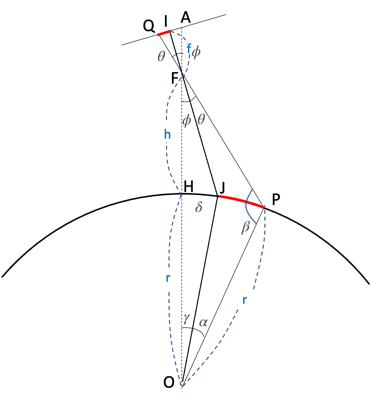        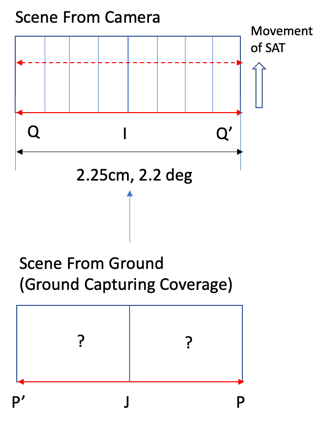


$$\begin{array}{l}
\angle \textrm{AFI}=\phi \;\left(\textrm{Tilted}\;\textrm{Angle}\right),\;\;\angle \textrm{IFQ}=\theta ,\;\;\angle \textrm{POJ}=\alpha ,\;\;\angle \textrm{OPF}=\beta ,\;\;\angle \textrm{HOJ}=\gamma ,\;\;\angle \textrm{OJF}=\delta \\
\bar{\textrm{FI}} =f,\;\;\bar{\textrm{FH}} =h,\;\tan \;\theta =\frac{x}{f}\;,\;\;\bar{\textrm{AF}} =\frac{\bar{\textrm{IF}} }{\cos \;\phi }\;\;\bar{\textrm{PJ}} =y\\
\left.1\right)\;\bar{\textrm{PH}} \\
\textrm{From}\;\triangle \textrm{FOP}\;\;\Rightarrow \;\;\angle \textrm{HFP}=\theta +\phi ,\;\;\bar{\textrm{FO}} =h+r,\;\;\bar{\textrm{PO}} =r\\
\\
\frac{r}{\sin \left(\theta +\phi \right)}=\frac{h+r}{\sin \;\beta }\;\;\Rightarrow \;\sin \;\beta =\frac{h+r}{r}\;\sin \left(\theta +\phi \right)\\
\\
\beta =\sin^{-1} \left\lbrace \frac{h+r}{r}\;\sin \left(\theta +\phi \right)\right\rbrace \;,\;\;\gamma +\alpha =\pi -\beta -\theta -\phi \\
\\
\left.2\right)\;\bar{\textrm{HJ}} \\
\textrm{From}\;\triangle \textrm{FOJ}\;\Rightarrow \;\;\angle \textrm{HFJ}=\phi ,\;\;\bar{\textrm{FO}} =h+r,\;\;\bar{\textrm{JO}} =r\\
\frac{r}{\sin \;\phi }=\frac{h+r}{\sin \;\delta }\Rightarrow \;\;\sin \;\delta =\frac{h+r}{r}\;\sin \;\phi \\
\\
\delta =\sin^{-1} \left\lbrace \frac{h+r}{r}\;\sin \;\phi \right\rbrace ,\;\gamma =\pi -\phi -\delta \\
\Longrightarrow \alpha =\left(\pi -\beta -\theta -\phi \right)-\left(\pi -\phi -\delta \right)=\delta -\beta -\theta \\
\bar{\textrm{PJ}} =r\alpha =r\left(\delta -\beta -\theta \right)
\end{array}$$


Code

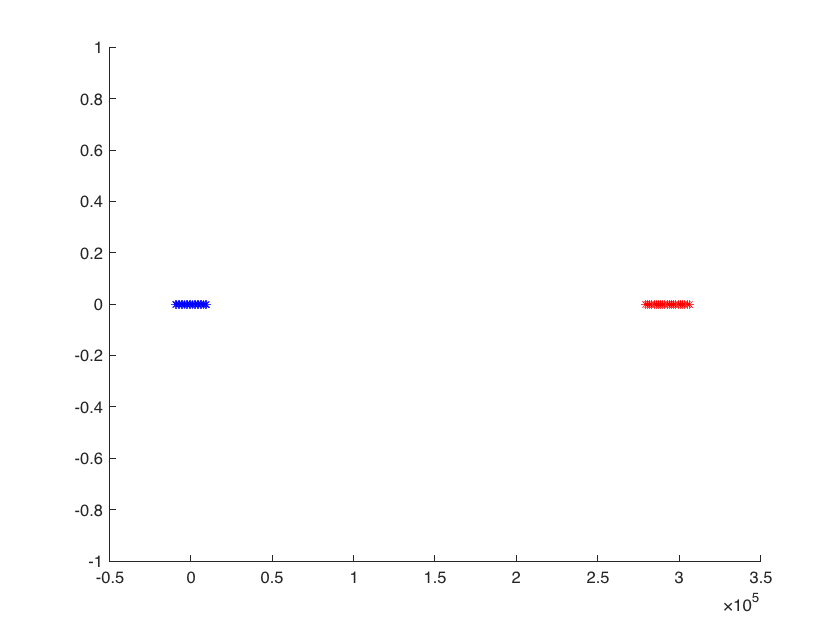

a = -1:0.1:1;
x_max = 2.2528/2;
x = x_max * a;

f = 58;

theta = atan(x/f);
%phi = roll angle
phi = 30 * (pi()/180);


h = 500*(10^3);
r = 6378*(10^3);

beta = pi() - asin((h+r)*sin(theta+phi)/r);


delta = pi() - asin((h+r)*sin(phi)/r);
gamma = pi() - phi - delta;

alpha = delta - beta - theta;
y2 = r * (gamma+alpha);


scatter(y2,0,'*','r')

## III. Position of Satellite / Position at Earth

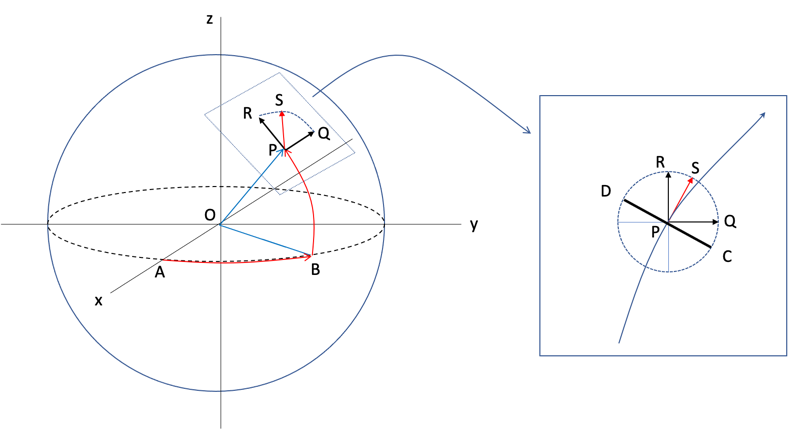


$$\begin{array}{l}
\angle \textrm{AOB}=\textrm{longitude}=\theta \;\;\left(-{180}^{\circ } <\theta <{180}^{\circ } \right)\\
\angle \textrm{BOP}=\textrm{latitude}=\phi \;\left(-{90}^{\circ } <\phi <{90}^{\circ } \right)\\
\\
\left.1\right)\;P\left(x,y,z\right)\\
z=\bar{\textrm{OP}} \;\sin \;\phi \;,\left(x,y\right)=\sqrt{\bar{\textrm{OP}} -z^2 }\left(\cos \;\theta ,\sin \;\theta \right)\\
\Longrightarrow P\left(x,y,z\right)=\left(\sqrt{\bar{\textrm{OP}} -z^2 }\cos \;\theta ,\sqrt{\bar{\textrm{OP}} -z^2 }\sin \;\theta ,\bar{\;\textrm{OP}} \;\sin \;\phi \;\right)\\
\\
\left.2\right)\;\bar{\textrm{PQ}} =\bar{\textrm{PS}} =\bar{\textrm{PR}} =1\;,\angle \textrm{SPQ}=\alpha \\
\overrightarrow{\textrm{PQ}} =\frac{1}{\sqrt{x^2 +y^2 }}\left(-y,x,0\right),\;\overrightarrow{\textrm{PR}} =\frac{\overrightarrow{\textrm{OP}} }{\sqrt{x^2 +y^2 +z^2 }}\;\times \;\overrightarrow{\textrm{PQ}} \\
\overrightarrow{\textrm{PS}} =\overrightarrow{\textrm{PQ}} \;\cos \;\alpha +\overrightarrow{\textrm{PR}} \;\sin \;\alpha \\
\\
\left.3\right)\;\bar{\textrm{PD}} ,\bar{\;\textrm{PC}} \\
\overrightarrow{\textrm{PD}} =-\overrightarrow{\textrm{PQ}} \;\sin \;\alpha +\overrightarrow{\textrm{PR}} \;\cos \;\alpha \;,\;\overrightarrow{\textrm{PC}} =-\overrightarrow{\textrm{PD}} 
\end{array}$$


long = 127.38;
lat = 36.35;
OP = 6378;
alpha = 30;

z = OP * sin(lat * pi()/180);
x = sqrt(OP^2-z^2) * cos(long*pi()/180);
y = sqrt(OP^2-z^2) * sin(long*pi()/180);

PQ = 1/(sqrt(x^2+y^2)) * [-y x 0];
PR = 1/(sqrt(x^2+y^2+z^2)) * cross([x y z], PQ);
PS = PQ * cos(alpha*pi()/180) + PR * sin(alpha*pi()/180);

PD = - PQ * sin(alpha*pi()/180) + PR * cos (alpha*pi()/180);
PC = - PD;

## IV. Tilted Angle GSD calculation with longitude/latitude

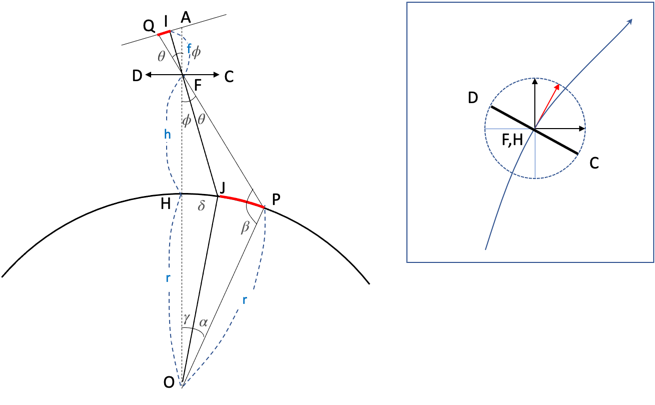


$$\begin{array}{l}
\gamma +\alpha =\pi -\beta -\theta -\phi :\textrm{calculated}\;\textrm{from}\;\textrm{II}\\
F,H:\textrm{From}\;\textrm{longitude}/\textrm{latitude}/\textrm{altitude}\\
\overrightarrow{\textrm{FC}} \;,\overrightarrow{\textrm{FD}} :\textrm{calculated}\;\textrm{from}\;\textrm{III}\\
\overrightarrow{\textrm{OH}} =\overrightarrow{a} ,\;r\;\overrightarrow{\textrm{FC}} =\overrightarrow{b} \\
\overrightarrow{\textrm{OP}} =\overrightarrow{a} \;\cos \left(\gamma +\alpha \right)+\overrightarrow{b} \sin \left(\gamma +\alpha \right)
\end{array}$$


long = 127.38;
lat = 36.35;

IQ = 2.2528/2;

f = 58;

theta = atan(IQ/f);
%phi = roll angle
phi = 30 * (pi()/180);

h = 500*(10^3);
r = 6378*(10^3);

%-----------------------------------


beta = pi() - asin((h+r)*sin(theta+phi)/r);


delta = pi() - asin((h+r)*sin(phi)/r);
gamma = pi() - phi - delta;
alpha = delta - beta - theta;
y2 = r * (gamma+alpha);

%----------------------------------

OH = [x, y, z];
FC = PC;
OP = OH * cos(alpha+gamma) + r/1000*FC*sin(gamma+alpha);
OJ = OH * cos(gamma) + r/1000*FC*sin(gamma);
OQ =  OH * cos(-alpha+gamma) + r/1000*FC*sin(gamma-alpha);
OH;
OJ;
OP;
OQ;

## IV. Data Cross Check


$$\begin{array}{l}
\textrm{Given}\;\textrm{Data}\\
\textrm{Satellite}\;\textrm{Altitude}:695\textrm{km}\\
\textrm{Satellite}\;\textrm{Position}\\
\textrm{ECEF}=\left\lbrack 6777587,-780889\ldotp 9,1860835\right\rbrack \\
\textrm{lat}=15\ldotp 345\\
\textrm{long}=-6\ldotp 572\\
\textrm{alt}=695\textrm{km}\\
\\
\textrm{Capturing}\;\textrm{Point}\\
\textrm{ECEF}=\left\lbrack 6081216,-1056093,1602128\right\rbrack \\
\textrm{lat}=14\ldotp 645\\
\textrm{long}=-9\ldotp 852\\
\textrm{alt}=0\\
\\
\textrm{Satellite}\;\textrm{Moving}\;\textrm{Direction}\\
\left\lbrack 4279\ldotp 5,2732\ldotp 438,-14319\ldotp 13\right\rbrack \\
\\
\textrm{Expected}\;\textrm{Roll}\;\textrm{Angle}:-27\ldotp 1
\end{array}$$


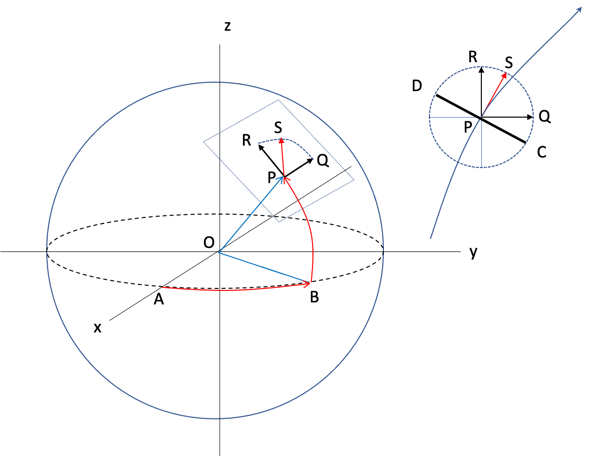

x = 6777.587;
y = -780.8899;
z = 1860.835; % Position of Satellite

PS_0 = [4279.5 2732.438 -14319.13]; % Satellite Moving Direction
phi = 30; % Roll Angle (Degree) -  direction (Left: +, Right: -)



r = 6378; % Radius of Earth (km)
h = 500; % Satellite Height (km)

phi = -phi* (pi()/180); % Rolling Angle Direction sign(+/-) modification (Left:-, Right:+)
PQ = 1/(sqrt(x^2+y^2)) * [-y x 0];
PR = 1/(sqrt(x^2+y^2+z^2)) * cross([x y z], PQ);
PS = PS_0/norm(PS_0);

if PS(3)>=0 %Satellite Moves north direction
    alpha = acos(dot(PQ,PS));
else %Satellite Moves south direction
    alpha = -acos(dot(PQ,PS));
end

PD = PQ * cos(alpha + pi()/2) + PR * sin((alpha+pi()/2));
PC = - PD;



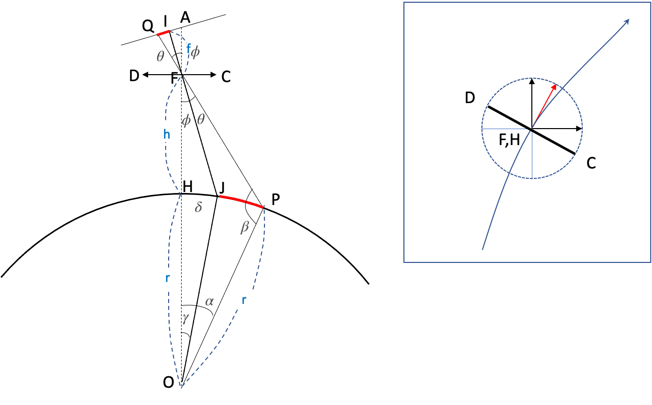

% Camera Lense Specification
IQ = 2.2528/2; % 4096 pixels * 5.5 micro M(cm)
f = 58; %Focal Length (cm)
theta = atan(IQ/f); %Half of Camera View Angle (rad)

% Calculating OJ,gamma: Center Point
if phi >= 0
    delta = pi() - asin((h+r)/r * sin(phi));
    gamma_abs = pi() - phi - delta;
    gamma = gamma_abs; % gamma >= 0
else
    delta = pi() - asin(sin(-phi)*(h+r)/r);
    gamma_abs = pi() - (-phi) - delta;
    gamma = - gamma_abs; % Gamma < 0
end

% Calculating OP, alpha: End Point 1
if phi+theta>=0
    beta = pi() - asin((h+r)/r * sin(phi+theta));
    alpha_abs = pi() - beta - (phi+theta);
    alpha = alpha_abs;
else
    beta = pi() - asin((h+r)/r* sin(-(phi+theta)));
    alpha_abs = pi() - beta - (-(phi+theta));
    alpha = -alpha_abs;
end

% Calculating OQ, zeta: End Point 2
if phi-theta>=0
    epsilon = pi() - asin((h+r)/r * sin(phi-theta));
    zeta_abs = pi() - epsilon - (phi-theta);
    zeta = zeta_abs;
else
    epsilon = pi() - asin((h+r)/r * sin(-(phi-theta)));
    zeta_abs = pi() - epsilon - (-(phi-theta));
    zeta = -zeta_abs;
end


SAT = [x y z]; % Location of Satellite
OH = [x y z]./(h+r)*r; % Location of Land point of Satellite
FC = PC;
 
OJ = OH * cos(gamma) + r * FC * sin(gamma); %Middle Point
OP = OH * cos(alpha) + r * FC * sin(alpha); % End Point 1
OQ = OH * cos(zeta) + r * FC * sin(zeta); % End Point 2

SAT % Location of Satellite

SAT = 	1.0e+03 *

    6.7776   -0.7809    1.8608


OH % Location of Land point of Satellite (km)

OH = 	1.0e+03 *

    6.2849   -0.7241    1.7256


OJ  %Middle Point of the GroundView (km)

OJ = 	1.0e+03 *

    6.2949   -0.4374    1.7833


OP % End Point 1 (km)

OP = 	1.0e+03 *

    6.2947   -0.4505    1.7807


OQ % End Point 2 (km)

OQ = 	1.0e+03 *

    6.2950   -0.4240    1.7859


norm(OP-OQ)

ans = 26.9920